%%%%%%%%%%%%%%%%%
% syms T(t)
% ode = (Kp + Ks)*T + b*diff(T,t) == Ks*To;
% 
% cond = T(0) == 0;
% TSol(t) = dsolve(ode, cond)



%%%%%%%%%%%%%%%%%%%%
syms s
ks = 400;
b = .5;
kp = 15;
tau = .07;
sys = tf(ks,[b*tau,b+tau*(ks+kp),ks+kp]);


% t = [0:.1:10]/1000;
% 
% u = ones(1,numel(t))/10;
% u(t>.005) = 0;
% lsim(sys,u,t)
% 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Fs = 1e5;
t = 0:1/Fs:.8;

hz = 20

hz = 20

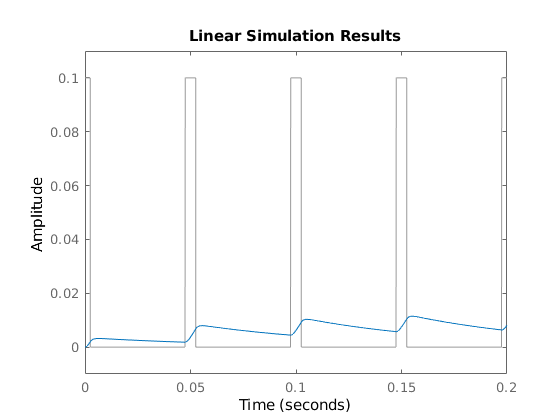

pulsewidth = .005;
pulseperiods = [0:1/hz:.8];

x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)
axis([0 .2 -0.01 0.11])



%%%%%%%%%%%%%%%%%%%%%%%%%%
Fs = 1e5;
t = 0:1/Fs:.5;

hz = 10

hz = 10

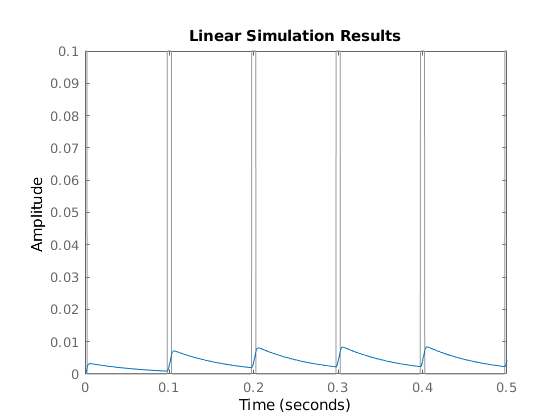

pulsewidth = .005;
pulseperiods = [0:1/hz:.5];
x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)



hz = 20

hz = 20

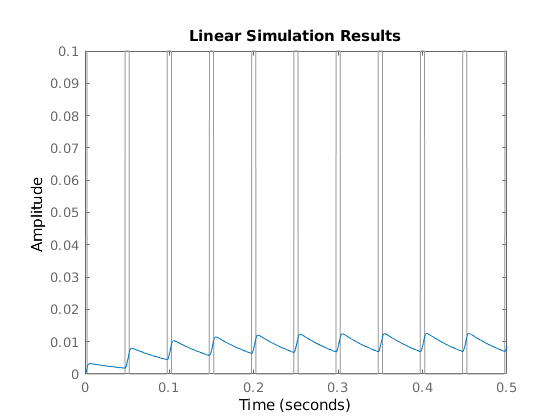

pulsewidth = .005;
pulseperiods = [0:1/hz:.5];
x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)


hz = 80

hz = 80

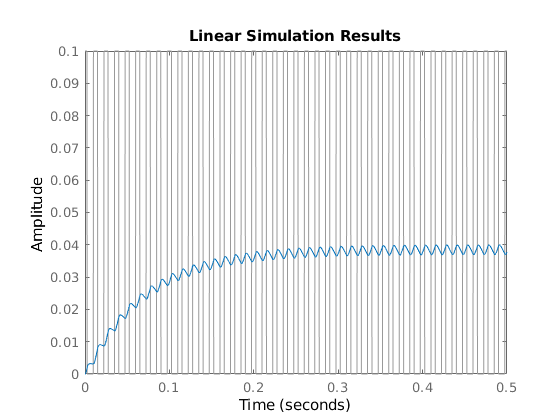

pulsewidth = .005;
pulseperiods = [0:1/hz:.5];
x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)